## 利用MLE方法估计参数

观测数据为：

A = [0 1 1 1 1];  % 阿根廷
B1 = [0 0 1 1 0];  % 厄瓜多尔
B2 = [0 0 1 1 1];

代入$p_A=0.803571429,q_B=0.857142857$，得到该比分的概率为：

p_sym_1 = simplify(ABAB_p(A,B1))

$$p\_sym\_1 = \left(\Delta +\mathrm{pA}\right)\,{\left(2\,\mathrm{al}-\mathrm{qB}\right)}^{2}\,\left(\Delta +\mathrm{pA}-1\right)\,\left(\Delta +\mathrm{qB}-1\right)\,{\left(\Delta +\mathrm{al}+\mathrm{pA}\right)}^{3}\,\left(\mathrm{al}-\mathrm{qB}+1\right)\,\left(2\,\mathrm{al}-\mathrm{qB}+1\right)$$

p_sym_2 = simplify(ABAB_p(A,B2))

$$p\_sym\_2 = -\left(\Delta +\mathrm{pA}\right)\,{\left(2\,\mathrm{al}-\mathrm{qB}\right)}^{3}\,\left(\Delta +\mathrm{pA}-1\right)\,\left(\Delta +\mathrm{qB}-1\right)\,{\left(\Delta +\mathrm{al}+\mathrm{pA}\right)}^{3}\,\left(\mathrm{al}-\mathrm{qB}+1\right)$$

syms pA qB al Delta
p_sym = simplify(p_sym_1+p_sym_2)

$$p\_sym = {\left(2\,\mathrm{al}-\mathrm{qB}\right)}^{2}\,\left(\Delta +\mathrm{qB}-1\right)\,{\left(\Delta +\mathrm{al}+\mathrm{pA}\right)}^{3}\,\left(\mathrm{al}-\mathrm{qB}+1\right)\,\left(\Delta^{2}+2\,\Delta \,\mathrm{pA}-\Delta +{\mathrm{pA}}^{2}-\mathrm{pA}\right)$$

p_sym = subs(p_sym,{pA,qB},{0.803571429,0.857142857})

$$p\_sym = \left(\Delta -\frac{1286742751964027}{9007199254740992}\right)\,\left(\mathrm{al}+\frac{1286742751964027}{9007199254740992}\right)\,{\left(2\,\mathrm{al}-\frac{7720456502776965}{9007199254740992}\right)}^{2}\,\left(\Delta^{2}+\frac{1367164174524729\,\Delta }{2251799813685248}-\frac{3201464520809033949993780298063}{20282409603651670423947251286016}\right)\,{\left(\Delta +\mathrm{al}+\frac{3618963988209977}{4503599627370496}\right)}^{3}$$

## 似然函数等高线图

得到数据：

% 各轮两队概率
p_fac = [pA+Delta+al,pA+Delta,1-pA-Delta, qB-2*al, 1-qB-Delta, 1-qB+al];  
p_fac = subs(p_fac,{pA,qB},{0.803571429,0.857142857});
[X,Y] = meshgrid(0:0.01:0.2,0:0.01:0.2);
Z = X;
for i = 1:size(Z,1)
    for j = 1:size(Z, 2)
        Z(i,j) = subs(p_sym,{al,Delta},{X(i,j),Y(i,j)});
        a = double(subs(p_fac,{al,Delta},{X(i,j),Y(i,j)}));
        if any(a<0 | a>1)
           Z(i,j) = 0;
        end
    end
end

绘图等高线图：

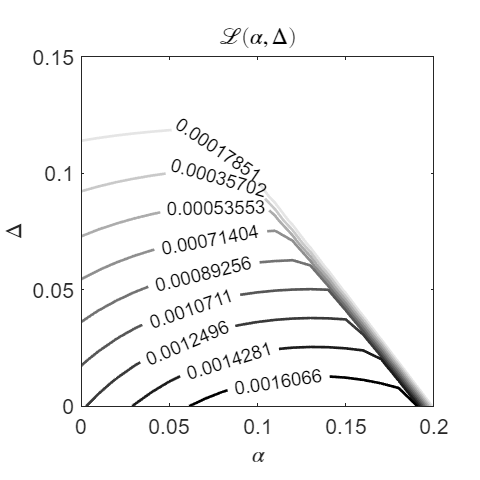

% 绘图
close all
f = figure('Units','inches','Position',[0 0 5 5]);
[M,c] = contour(X,Y,Z,9);
ylim([0,0.15]);
xlim([0, 0.2])
c.LineWidth = 2;
c.ShowText = 'off';
clabel(M,c,'FontSize',14);
xlabel('$\alpha$','Interpreter','latex','FontSize',16);
ylabel('$\Delta$','Interpreter','latex','FontSize',16);
str = "$\mathcal{L}(\alpha,\,\Delta)$";
title(str,'Interpreter','latex','FontSize',16);
set(gca,'fontsize',16);
cl = gray;
cl = flipud(cl(1:230,:));
colormap(cl);
pbaspect([1 0.99 1])
clabel(M, c, 'LabelSpacing', 100000); % 设置较大的标签间距


%exportgraphics(gcf,'pic/Delta_alpha_est_2_1.pdf','ContentType','vector','Resolution',300);

## MAP的等高线图

先验分布：

syms m1 s1 x
PP = 1/(s1*sqrt(2*pi))*exp(-(x-m1)^2/(2*s1^2))

$$PP = \frac{2251799813685248\,{\mathrm{e}}^{-\frac{{\left(m_{1}-x\right)}^{2}}{2\,{s_{1}}^{2}}}}{5644425081792261\,s_{1}}$$

PP

$$PP = \frac{2251799813685248\,{\mathrm{e}}^{-\frac{{\left(m_{1}-x\right)}^{2}}{2\,{s_{1}}^{2}}}}{5644425081792261\,s_{1}}$$

PP_al = subs(PP, {m1, s1}, {0, 0.5})

$$PP\_al = \frac{4503599627370496\,{\mathrm{e}}^{-2\,x^{2}}}{5644425081792261}$$

PP_Delta = subs(PP, {m1, s1}, {0, 0.5})

$$PP\_Delta = \frac{4503599627370496\,{\mathrm{e}}^{-2\,x^{2}}}{5644425081792261}$$

Z1 = X;
for i = 1:size(Z1,1)
    for j = 1:size(Z1, 2)
        Z1(i,j) = subs(PP_al,{x},{X(i,j)}) * subs(PP_Delta,{x},{Y(i,j)});
    end
end

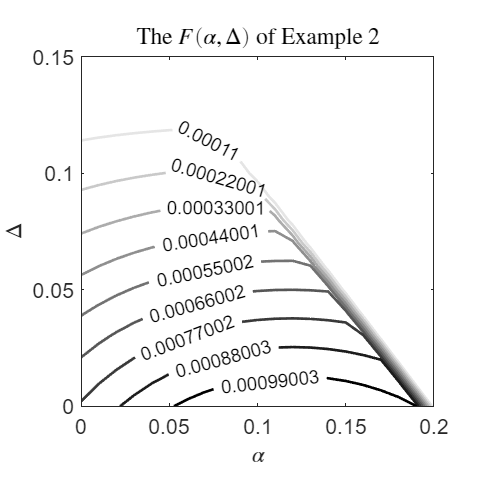

% 绘图
Z0  = Z .* Z1;
close all
f = figure('Units','inches','Position',[0 0 5 5]);
[M,c] = contour(X,Y,Z0,9);
ylim([0,0.15]);
xlim([0, 0.2]);
c.LineWidth = 2;
c.ShowText = 'on';
clabel(M,c,'FontSize',14) 
xlabel('$\alpha$','Interpreter','latex','FontSize',16);
ylabel('$\Delta$','Interpreter','latex','FontSize',16);
str = "The $F(\alpha,\,\Delta)$ of Example 2";
title(str,'Interpreter','latex','FontSize',16);
set(gca,'fontsize',16);
cl = gray;
cl = flipud(cl(1:230,:));
colormap(cl);
pbaspect([1 0.99 1])
clabel(M, c, 'LabelSpacing', 100000); % 设置较大的标签间距

%clabel(M,c,'manual','FontSize',14, 'BackgroundColor', 'white'); 

%exportgraphics(gcf,'pic/MAP_2.pdf','ContentType','vector','Resolution',300);